**Project 3: Autonomous Cart Speed Profile (Quadratic + Numerical Change)**

v(t) = −0.2(t − 10)2 + 20

for 0 ≤ t ≤ 20 seconds.

Tasks

1. Implement v(t) and evaluate it on t = 0 : 0.2 : 20.

2. Plot speed vs time.

3. Use numerical differences to estimate the acceleration a(t) ≈ ∆v

∆t .

4. Plot acceleration vs time on a separate figure.

5. Identify the time when speed is maximized and interpret what acceleration is near that time.

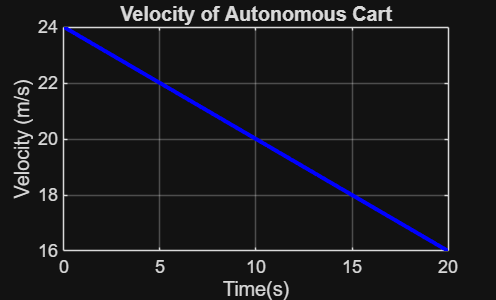

t = 0:0.2:20; %Time intervals
v = -0.2*(t-10)*2 + 20; %the velocity of the autonomous cart function

%lines 5 to 12 allows for a visual
figure(1); %first figure 
plot (t,v, 'b', 'LineWidth', 2); %Plots both variables 
grid on; %turns on the grid
xlabel('Time(s)'); %labels x axis 
ylabel('Velocity (m/s)'); %labels y axis 
title('Velocity of Autonomous Cart'); %Adds a title to graph

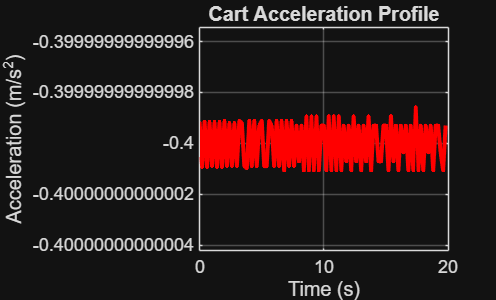


dv = diff(v); %allowing dv to be the change in velocity
dt = diff(t); %allowing dt to be the change in time

a = dv ./ dt; % Acceleration is defined as change in velocity/change in time

t_accel = t(1:end-1); % Because 'diff' makes the array shorter by 1, we adjust the time array for plotting

%Plotting acceleration function 
figure(2); %second figure 
plot(t_accel, a, 'r', 'LineWidth', 2); %plotting acceleration and time
grid on; %allows for a grid 
xlabel('Time (s)'); %defining time for x axis 
ylabel('Acceleration (m/s^2)'); %defining acceleration on the y axis 
title('Cart Acceleration Profile'); %creates a title for the graph 


%% 5. Max Speed Analysis
[max_v, idx] = max(v); %limits 
t_max = t(idx); %limits 

fprintf('Maximum Speed: %.2f m/s occurs at t = %.2f seconds.\n', max_v, t_max); %This prints a maximum speed below the graphs 

Maximum Speed: 24.00 m/s occurs at t = 0.00 seconds.


fprintf('Acceleration near max speed is approximately 0 m/s^2.\n'); %prints a message saying the acceleration is approx. 0m/s^2

Acceleration near max speed is approximately 0 m/s^2.
